% a, alpha, d, theta
t1 = 0;
t2 = 0;
t3 = 0;
t4 = 0;
dhparams = [0   	-pi/2	0.0919 t1;
            0.096	0       0       t2;
            0.096	0	0	t3;
            0.047  	0	0	t4]

robot = rigidBodyTree;

bodies = cell(4,1);
joints = cell(4,1);
for i = 1:4
    bodies{i} = rigidBody(['body' num2str(i)]);
    joints{i} = rigidBodyJoint(['jnt' num2str(i)],"revolute");
    setFixedTransform(joints{i},dhparams(i,:),"dh");
    bodies{i}.Joint = joints{i};
    if i == 1 % Add first body to base
        addBody(robot,bodies{i},"base")
    else % Add current body to previous body by name
        addBody(robot,bodies{i},bodies{i-1}.Name)
    end
end

config = homeConfiguration(robot)

config = 1×4 struct array with fields:
    JointName
    JointPosition


config(2).JointPosition = pi/2;
showdetails(robot)

--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


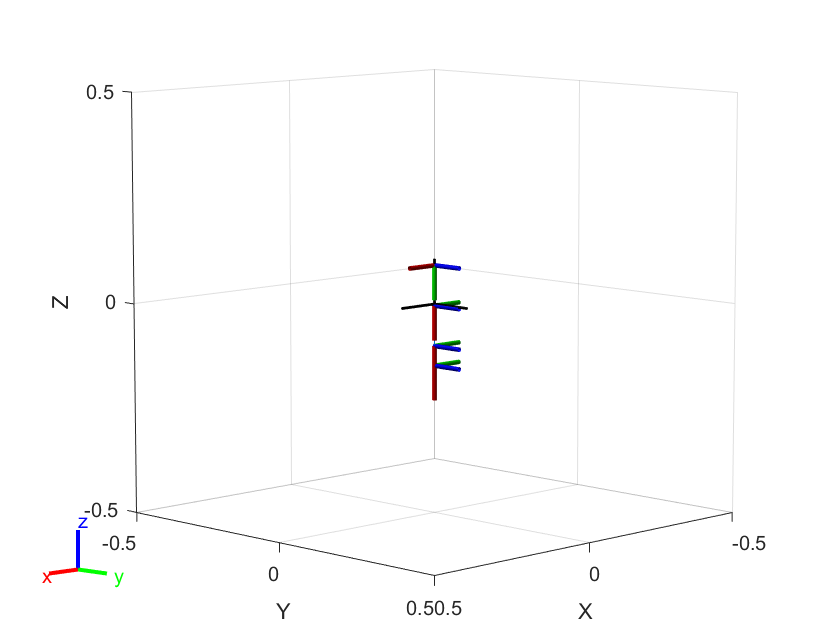

figure(Name="RRRR Robot Model")
show(robot,config);

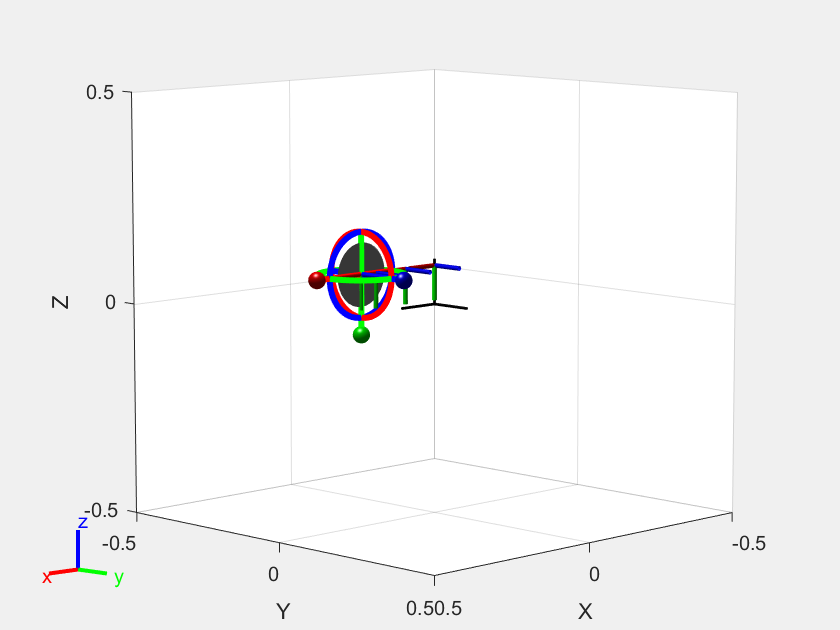

%figure(Name="Interactive GUI")
gui = interactiveRigidBodyTree(robot,MarkerScaleFactor=0.5);

q0 = homeConfiguration(robot);
ndof = length(q0);
count=10;
qs = zeros(count, ndof);

ik = inverseKinematics('RigidBodyTree',robot);
weights = [0.1, 0.1, 0, 1, 1, 1];
endEffector = 'tool';

qInitial = q0; % Use home configuration as the initial guess
for i = 1:count
    % Solve for the configuration satisfying the desired end effector
    % position
    point = points(i,:);
    qSol = ik(endEffector,trvec2tform(point),weights,qInitial);
    % Store the configuration
    qs(i,:) = qSol;
    % Start from prior solution
    qInitial = qSol;
end

Unrecognized function or variable 'points'.

figure
show(robot,qs(1,:)');
ax = gca;
ax.Projection = 'orthographic';
hold on
plot3(points(:,1),points(:,2),points(:,3),'k')
view([-37.5 30])
% Set up animation. Show robot in each configuration on trajectory
framesPerSecond = 7;
r = rateControl(framesPerSecond);
for i = 1:count
    show(robot,qs(i,:)','PreservePlot',false);
    drawnow
    waitfor(r);
end

clear;
rob = MyRobot();

Succeeded to open the port!
Succeeded to change the baudrate!
Initial Joint Angles: 
[ID:002] Pos:8.584000e+01
[ID:001] Pos:00
[ID:010] Pos:1.331100e+02[TxRxResult] There is no status packet!

[ID:000] Pos:00
[TxRxResult] There is no status packet!
Set initial speed to [05, 0.3, 0.3, 0.3][TxRxResult] There is no status packet!

Set initial torque limit to [1 1 1 1]

try
%rob.set_speed([0.1,0.1,0.1,0.1]);
rob.move_c(0,0.1,0.2);
rob.disable_motors();

catch
rob.disable_motors()
end

Status: 'best available', using Angles:
-0.310814°  -153.679993°  80.000000°  74.015674°  


Dynamixel succesfully disconnected[TxRxResult] Incorrect status packet!

Dynamixel succesfully disconnected[TxRxResult] There is no status packet!
